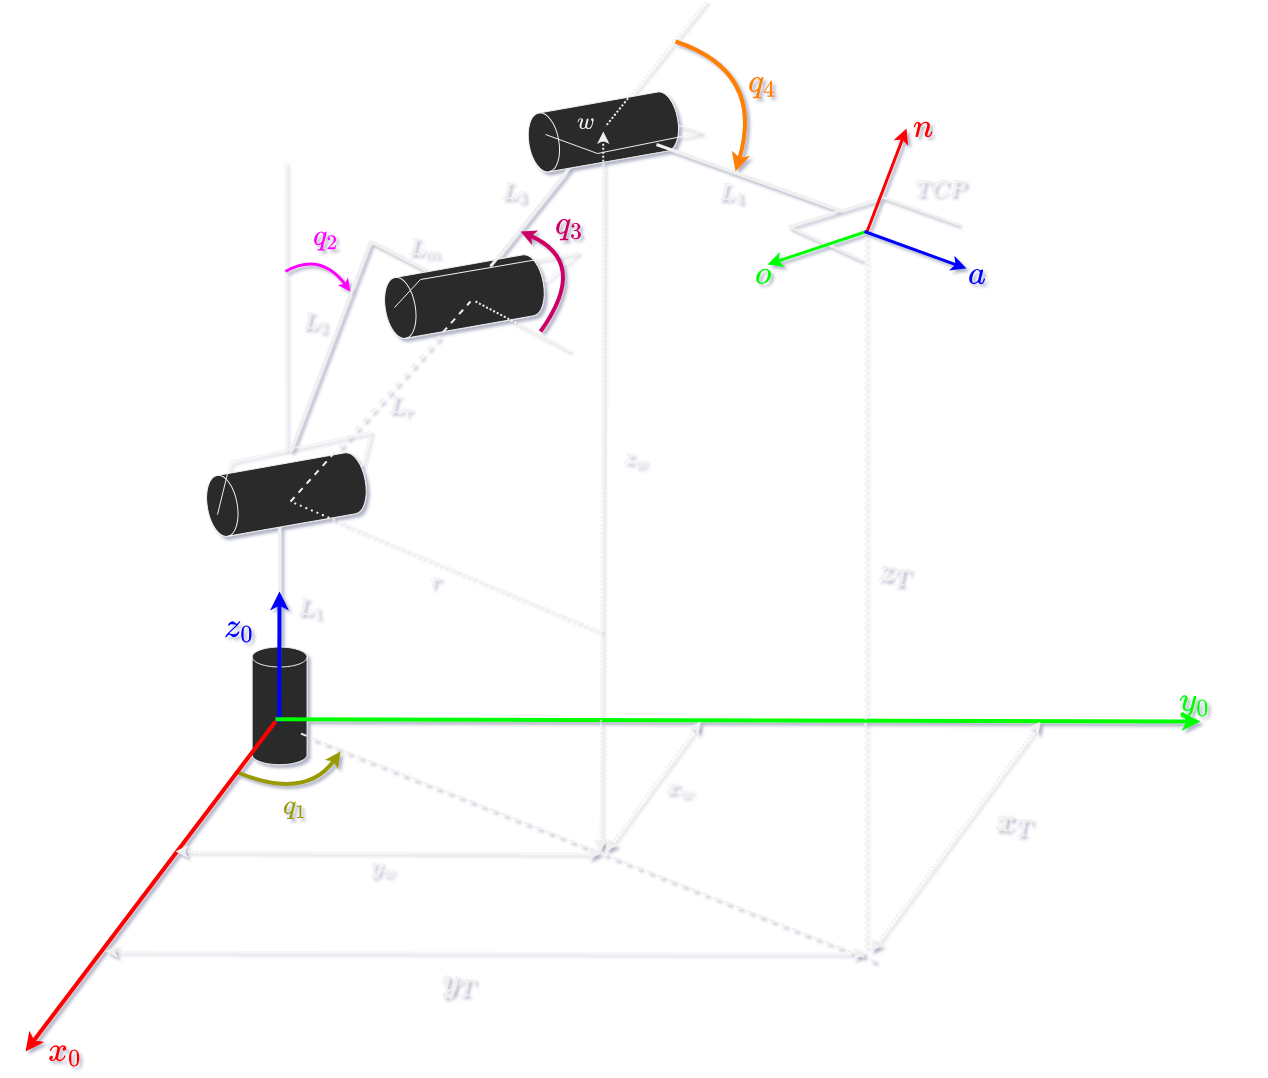

clc, clear, close all
% Parámetros robot
q1 = 1;
q2 = 1;
q3 = 1;
q4 = 1;

L1 = 0.0455; %m
L2 = 0.103; %m
L3 = 0.103; %m
L4 = 0.11; %m (TCP)
Lm = 0.0315; %m  

% Creación robot 
% DH = [THETA D A ALPHA SIGMA OFFSET] 
DH = [q1	L1	0	            -pi/2	0	0;
      q2	0	sqrt(L2^2+Lm^2)	0	    0	-pi/2;
      q3	0	L3	            0	    0	0;
      q4	0	L4	            0	    0	0];

for i=1:size(DH)
    L(i) = Link(DH(i,:));
end

Phantom = SerialLink(L,'name','Phantom','tool',trotx(-pi/2)*troty(pi/2))

 
Phantom = 
 
Phantom (4 axis, RRRR, stdDH, fastRNE)                           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|     0.0455|          0|     -1.571|          0|
|  2|         q2|          0|     0.1077|          0|     -1.571|
|  3|         q3|          0|      0.103|          0|          0|
|  4|         q4|          0|       0.11|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =   0  0  1  0             
          0         0  1  0  0           -1  0  0  0             
       9.81         0  0  1  0            0 -1  0  0             
                    0  0  0  1            0  0  0  1         

% Fkine
target1 = deg2rad([0 0 0 0]);
target2 = deg2rad([25 25 20 -20]);
target3 = deg2rad([-35 35 -30 30]);
target4 = deg2rad([85 -20 55 25]);
target5 = deg2rad([80 -35 55 -45]);

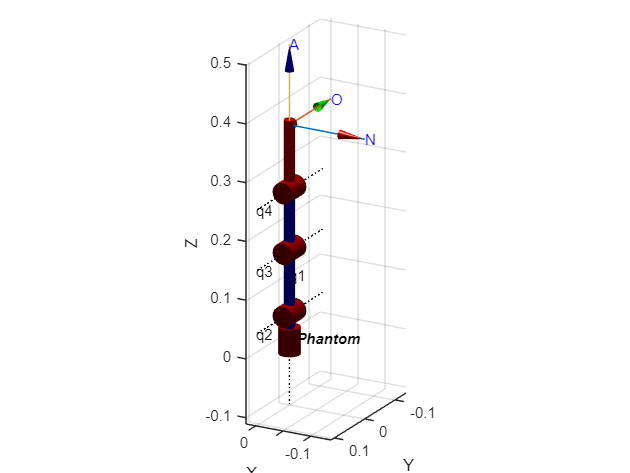

figure();
Phantom = SerialLink(L,'name','Phantom','tool',trotx(-pi/2)*troty(pi/2));
view([208.885 20.346]);
Phantom.plot(target1,'noa','jaxes','notiles','floorlevel',0,'noshadow','delay',1);
axis tight;

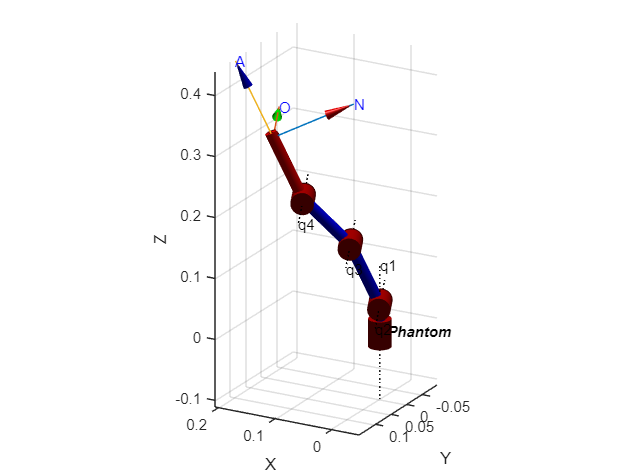

figure();
Phantom = SerialLink(L,'name','Phantom','tool',trotx(-pi/2)*troty(pi/2));
view([208.885 20.346]);
Phantom.plot(target2,'noa','jaxes','notiles','floorlevel',0,'noshadow','delay',1);
axis tight;

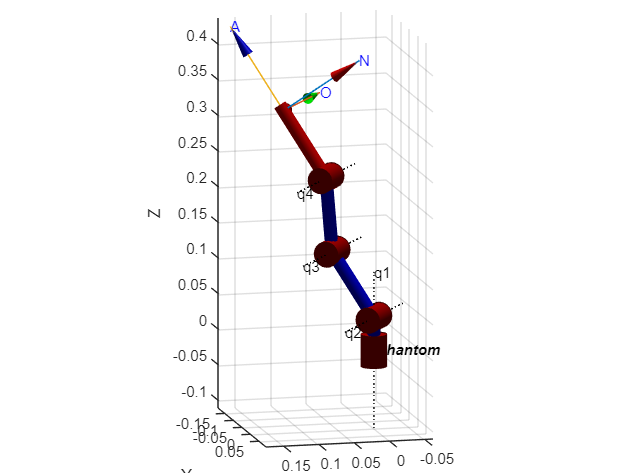

figure();
Phantom = SerialLink(L,'name','Phantom','tool',trotx(-pi/2)*troty(pi/2));
view([166.425 11.357]);
Phantom.plot(target3,'noa','jaxes','notiles','floorlevel',0,'noshadow','delay',1);
axis tight;

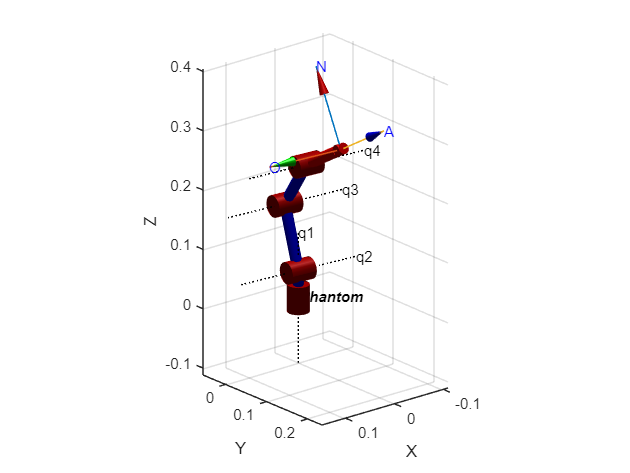

figure();
Phantom = SerialLink(L,'name','Phantom','tool',trotx(-pi/2)*troty(pi/2));
view([140.155 20.854]);
Phantom.plot(target4,'noa','jaxes','notiles','floorlevel',0,'noshadow','delay',1);
axis tight;

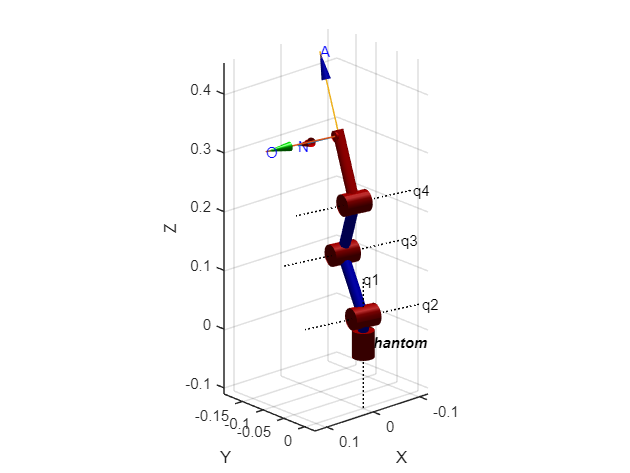

figure();
Phantom = SerialLink(L,'name','Phantom','tool',trotx(-pi/2)*troty(pi/2));
view([138.135 20.980]);
Phantom.plot(target5,'noa','jaxes','notiles','floorlevel',0,'noshadow','delay',1);
axis tight;